% you need to CROP 1st, begore making onsetDF
% you need to do onsetDf before you can subtract a baseline

% let's not subtract anything, just graphically plot 10 frames
% at full contrast

clear seventhConTrials % use highest contrast, all durations
     
% conOrderedByTrialMeetCriteria = conOrderedByTrial(idxOnsetFramesMeetBothCriteria);
seventhConTrials = conOrderedByTrial == uniqueContrasts(7);
 
clear frames
frames = 1:size(onsetDf,3);

clear frames4title
%frames4title = {'f 9';'f 10';'f 11';'f 12';'f 13';'f 14';'f 15';'f 16';'f 17';'f 18';};

range = [-0.035 0.035];

figure
suptitle('peri-stim frames, no baseline subtraction, highest Con')

clear f
for f = 1:length(frames)
        
     subplot(4,6,f)
    
     % show each frame
     imagesc(mean(onsetDf(:,:,frames(f),seventhConTrials),4),range); % ,range
    
     % st = title(sprintf('%s', frames4title{f}));
    
     axis off;
     axis image;
    

    
%     clear st
%     st = title(sprintf('%s', frames4title{i}));
%     set(st, 'FontSize', 10);
   
end


% get onsetDf index for baseline frames - the 4 frames that preceed stimulus onset

numBaselineFrame = 3;
stimOnsetFrame = numBaselineFrame+2; % stim onset is always 2 frames ahead of the last baseline frame

clear baselineIdx
% store index of each baseline frame
for b = 1:numBaselineFrame
    % this time, EXCLUE the frame immediately prior to onset 
    % (theory that between the 1st 0.1Hz imagaing frame after stim onset (monitor)
    % and the next previous (pre-stim onset) imaging frame, 
    % the monitor displayed the stimulus onset (so before the 1st im frame
    % following stim onset, and after the last im frame before stim onset,
    % but still during the 50 ms time period that the im frame is being taken
    % what if stim starts there and affects the frame before stim onset as well?
    if b <= 4
       b = b+1; % because we never wanna subtract 1 from the stim onset 
       % (don't index the frame before stim onset)
       baselineIdx(b-1) = stimOnsetFrame-b; % b-1 cuz want list of indicies to start
       % at first cell in baselineIdx
       
    end 
    
end
% this is the index for the baseline frames, regardless of what onset range was picked
baselineIdx = flip(baselineIdx);


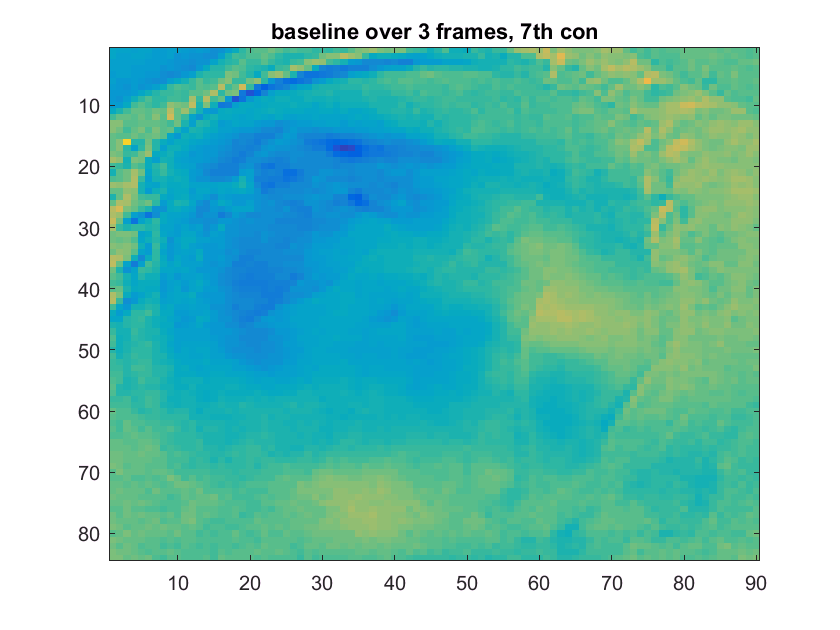

% now where where you might need to INDEX into 
% specific TRIALS

% index into those frames and take mean/get mean image
clear allBaselineFrameOnsetDf

% maybe get baseline frames for all trials first, then screen by 
% max contrast at the very end? So that transition step vars are more generalizable?
% actually maybe take just 7th C trialsafter taking abseline for all trials
% but before doing any averaging at all, b/c we only want 7thC trials

% this matrix is importatn, because it's the full images of the 4 baseline frames,
% across all points, all stimulus conditions
allBaselineFrameOnsetDf = onsetDf(:,:,baselineIdx,:);

% for just 1 frame as baseline:
% allBaselineFrameOnsetDf = onsetDf(:,:,1,:);

% now we can get selective
clear seventhBaselineFrameOnsetDf
clear meanBaselineImage
clear meanBaselineImage7thTrials

% get highest contrast trials only
seventhBaselineFrameOnsetDf = allBaselineFrameOnsetDf(:,:,:,seventhConTrials);
% NOW we can safely average over frames
meanBaselineImage = mean(seventhBaselineFrameOnsetDf,3); % 3rd dim is frames
meanBaselineImage = squeeze(meanBaselineImage);
% then take mean across trials
meanBaselineImage7thTrials = mean(meanBaselineImage,3);

range = [-0.008 0.005];
imagesc(meanBaselineImage7thTrials,range) % ,range
title('baseline over 3 frames, 7th con')

% plot all frames with mean baseline subtracted

clear seventhConTrials
seventhConTrials = conOrderedByTrial == uniqueContrasts(7);
 
%clear frames
% frames = [9 10 11 12 13 14 15 16 17 18];

%clear frames4title
% frames4title = {'f 9';'f 10';'f 11';'f 12';'f 13';'f 14';'f 15';'f 16';'f 17';'f 18';};

range = [0 0.04]; 

%clear baselineFrameSubtracted4title;
% baselineFrameSubtracted4title = '10';

figure
suptitle('peri-stim frames, w/baseline subtraction')

clear frames
frames = 1:size(onsetDf,3); % for every frame, subtract the baseline frame

for f = 1:length(frames)
    
    subplot(4,6,f)
    
    % subtract baseline frame from every frame
    %imagesc(mean(onsetDf(:,:,frames(f),seventhConTrials),4)-mean(onsetDf(:,:,baselineFrameSubtracted,seventhConTrials),4)) 
   
    %range = [-0.008 0.005];
    imagesc(mean(onsetDf(:,:,frames(f),seventhConTrials),4)-meanBaselineImage7thTrials,range) %,range
    %st = title(sprintf('%s', frames4title{f}));
    
    axis off;
    axis image
    
%     clear st
%     st = title(sprintf('%s', frames4title{i}));
%     set(st, 'FontSize', 10);
    
    % s = s + 1;

end

